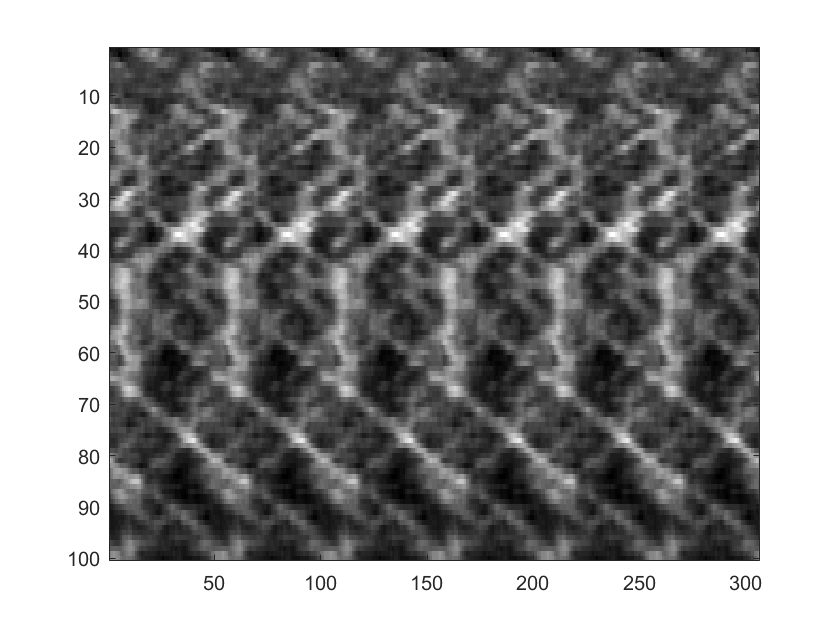

fname1 = '.\testing\testKymographs\SM1_JF-549_500ms.exp_50.Power_100x6s_3_MMStack_Pos0.ome_denoise_reg_ring15_kymoWrap.tif';
fname2 = '.\testing\testKymographs\180327_Sam1_1mW_RingHiLO_1_MMStack_Pos0.ome_denoise_reg_ring1_kymoWrap.tif';

im1 = imread(fname1);
im1(end,:)=[];%remove the last black (non-data) row
imagesc(im1);
colormap gray

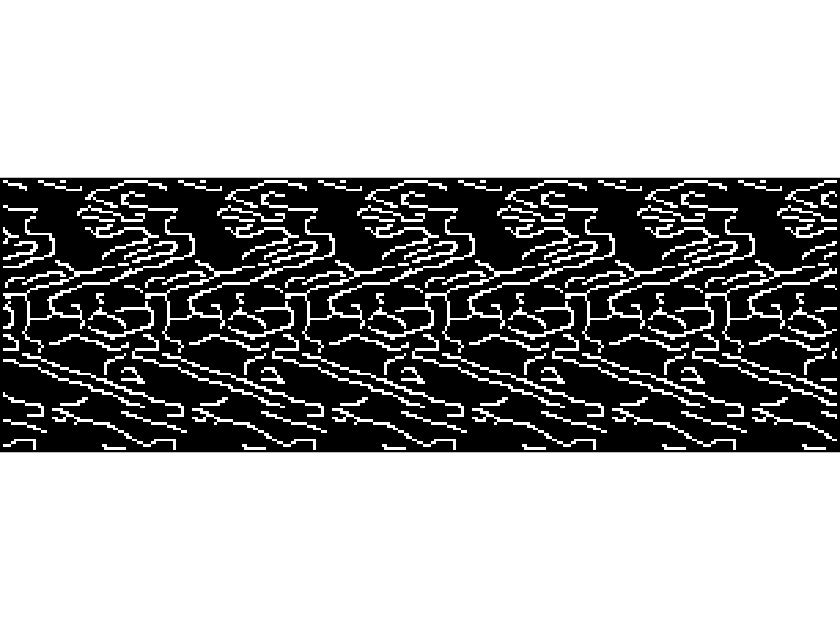

% try the canny and ridge detectors
BW = edge(im1,'canny');
imshow(BW)

Edge finding is a bit annoying as it finds the filament sides not the centre (although could be useful eg for nicks stuff

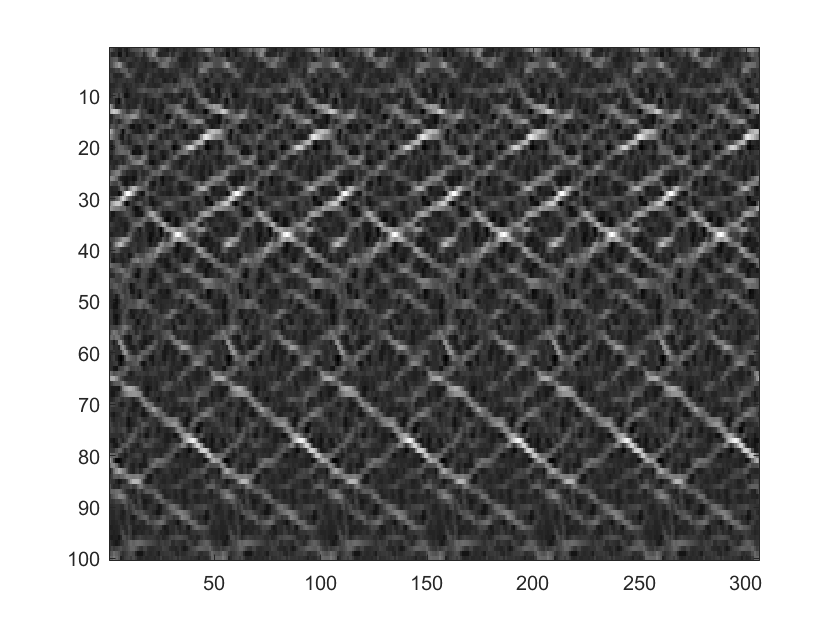

%try the ridge filter
ridge=ridgefilter(im1);
figure;
imagesc(ridge);
colormap gray

level = graythresh(ridge)

level = 0.5255

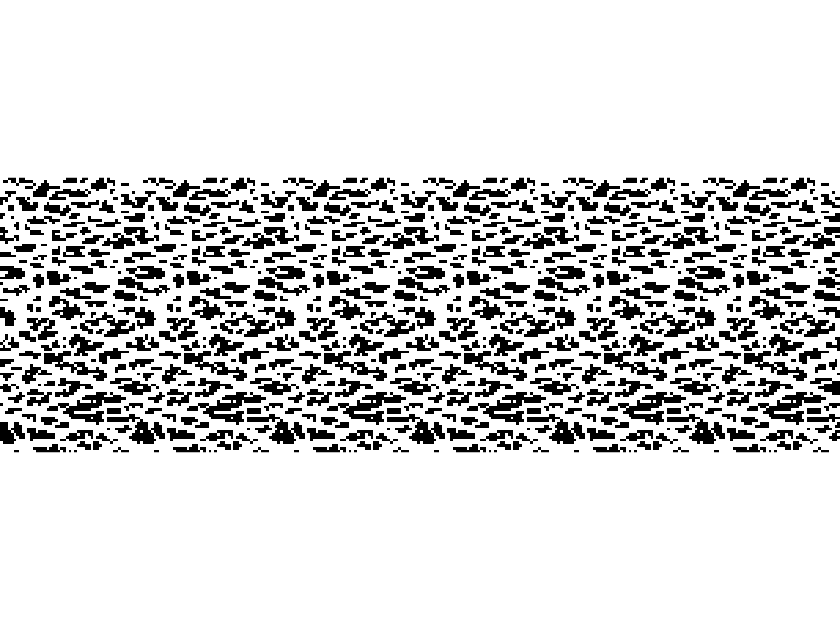

ridgeBW=imbinarize(ridge,level);
imshow(ridgeBW);

looks promising but might need to skeletonize?

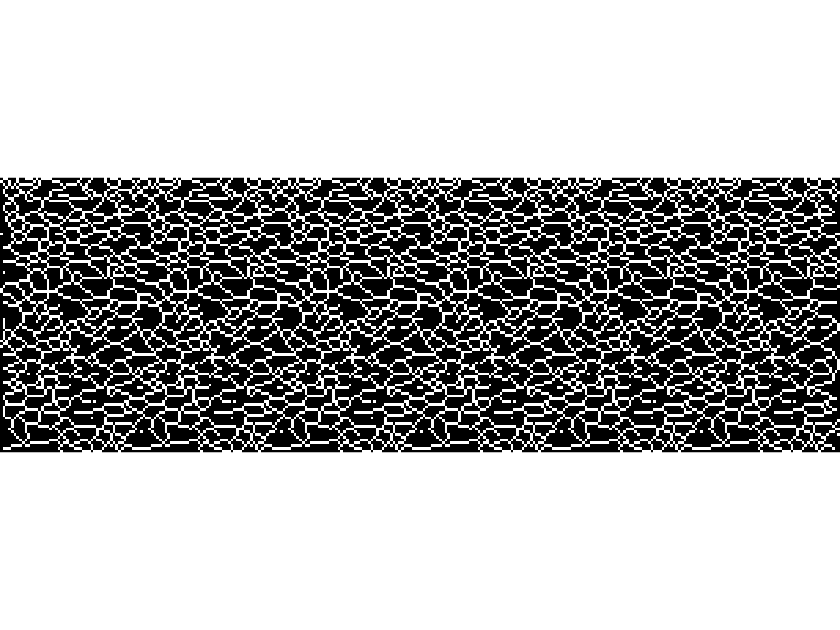

imskel = bwskel(ridgeBW);
imshow(imskel);

not good. 

but ridge filtering followed by threshold or especially local threshold could be promising

with a gaussian blur

Outline alg:

a) Ridge finder: (binary output)

- Gaussian blur

- Ridge filter

- Local threshold

b) Hough transform

Ridge Finder

 [BW ridge] = ridgefinder(im1, 2);

T =     0.3452    0.3518    0.3603    0.3694    0.3774    0.3831    0.3864    0.3873    0.3864    0.3847    0.3827    0.3802    0.3764    0.3707    0.3627    0.3530    0.3431    0.3347    0.3290    0.3257    0.3242    0.3248    0.3290    0.3384    0.3516    0.3650    0.3758    0.3825    0.3851    0.3851    0.3845    0.3837    0.3818    0.3784    0.3735    0.3679    0.3622    0.3553    0.3477    0.3408    0.3341    0.3264    0.3182    0.3108    0.3059    0.3045    0.3064    0.3098    0.3134    0.3186
    0.3303    0.3356    0.3428    0.3506    0.3573    0.3620    0.3643    0.3645    0.3632    0.3611    0.3588    0.3560    0.3520    0.3464    0.3393    0.3316    0.3239    0.3181    0.3147    0.3136    0.3138    0.3156    0.3199    0.3286    0.3406    0.3527    0.3624    0.3686    0.3714    0.3718    0.3717    0.3712    0.3698    0.3674    0.3638    0.3596    0.3553    0.3498    0.3435    0.3377    0.3318    0.3249    0.3173    0.3104    0.3056    0.3040    0.3055    0.3087    0.3120    0

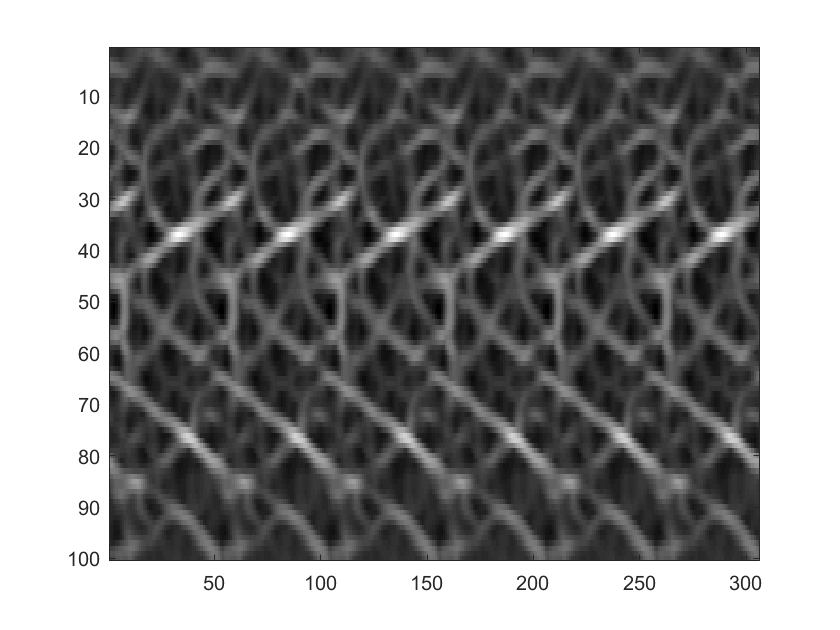

 imagesc(ridge);colormap gray

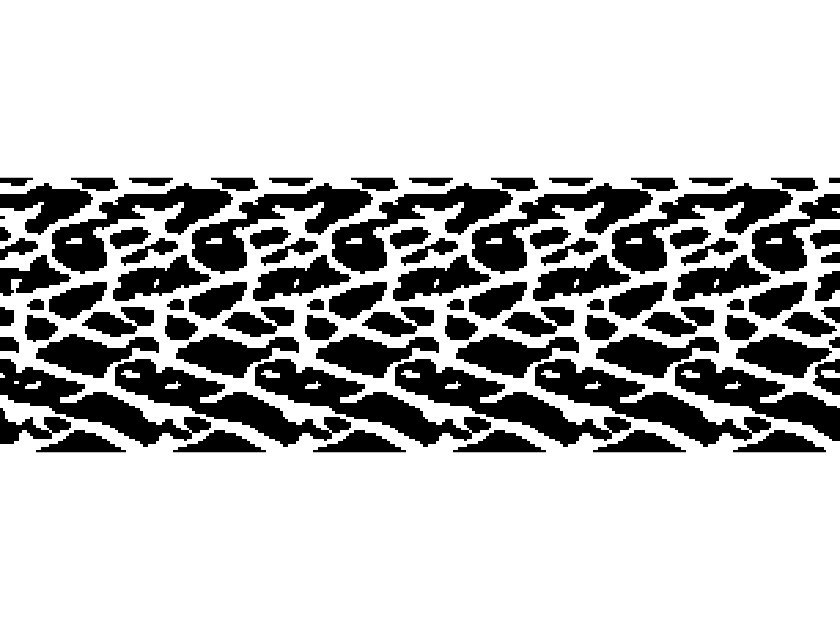

 imshow(BW)

Looks pretty promising to me

What about the hough transform

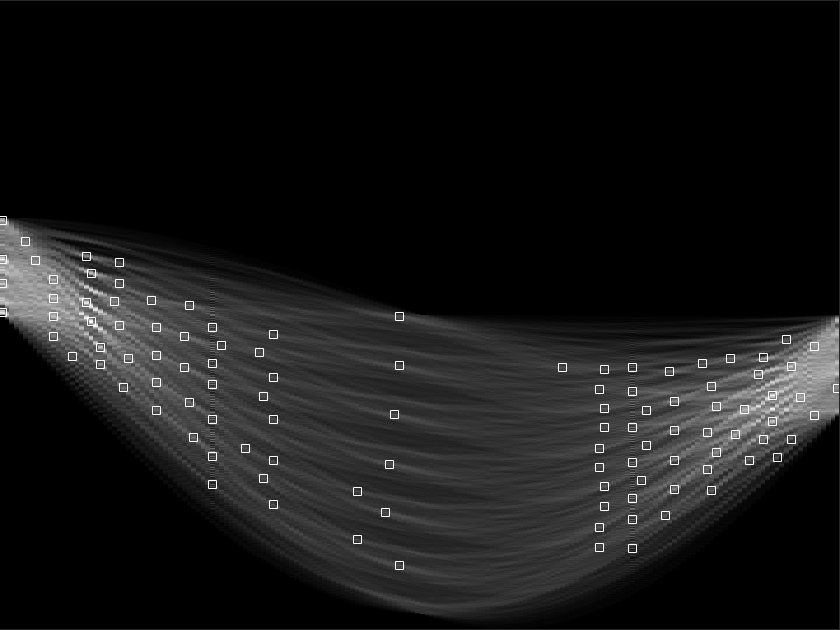

 [H,T,R] = hough(BW);
 figure
imshow(H,[],'XData',T,'YData',R,...
            'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
MAXPEAK =1000;
thresh = ceil(0.3*max(H(:)));
suppressNHood = [21 11];%rho theta
suppressNHood = size(H)/20; %rho theta
suppressNHood = max(2*ceil(suppressNHood/2) + 1, 1);
P  = houghpeaks(H,MAXPEAK,'threshold',thresh,'NHoodSize', suppressNHood);
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

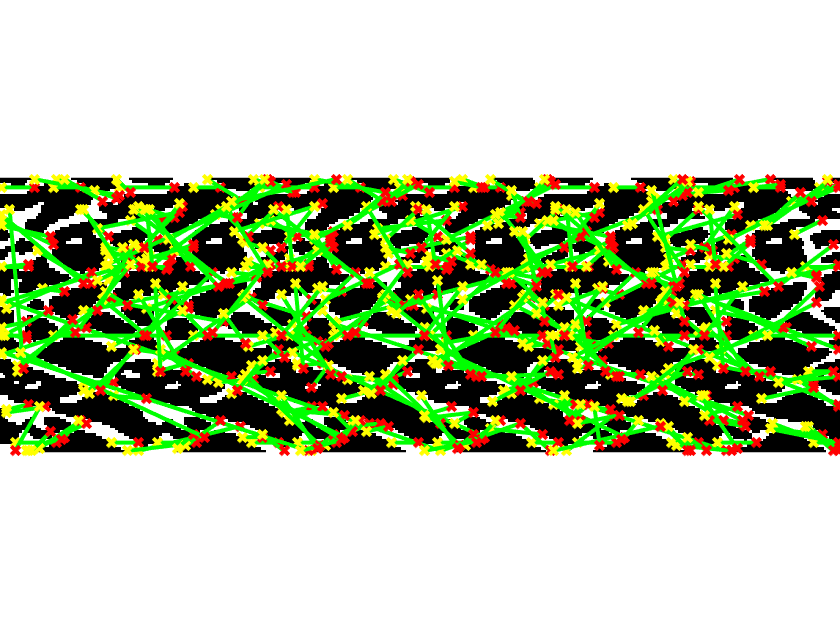

lines = houghlines(BW,T,R,P,'FillGap',5,'MinLength',7);
figure, imshow(BW), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end